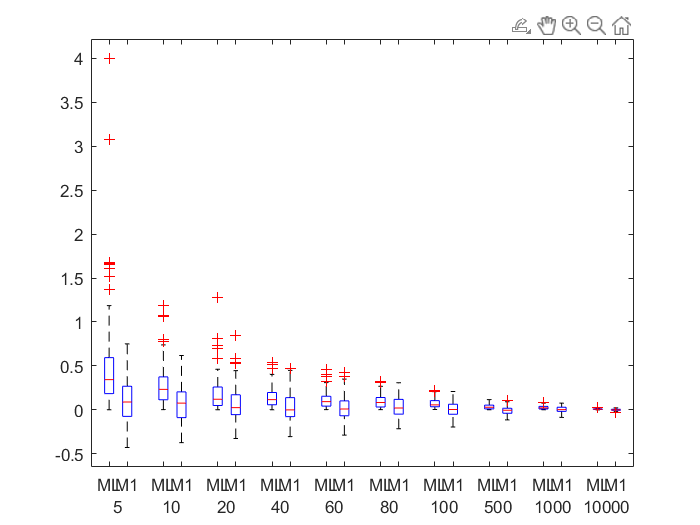

N_arr=[5, 10, 20, 40, 60, 80, 100, 500, 1000, 10000];%Array to store sample sizes
MLE=zeros(100, 10);%To store error in MLE
MP1=zeros(100, 10);%To store error in posterior mean

rng(1);
for i = 1:10
    N=N_arr(i);
    for n=1:100
        a=zeros(N, 1);
        for j=1:N
            a(j)=(-1/5)*(log(rand()));%Generating a random variable as given in the question
        end
        MLE(n,i)=abs(N/sum(a)-5)/5;%Inverse of sample mean error
        MP1(n,i)=(((N+5.5)/(sum(a)+1))-5)/5;%Error in posterior mean
            
    end
end
data={MLE, MP1};
boxplotGroup(data, 'PrimaryLabels', {'ML', 'M1'}, 'SecondaryLabels', {'5', '10', '20', '40', '60', '80', '100', '500', '1000', '10000'});